rayChan1 = comm.RayleighChannel('SampleRate',1e5,'MaximumDopplerShift',130); % Rayleigh fading channel object
rayChan1.Visualization = 'Impulse response'

rayChan1 =   comm.RayleighChannel with properties:

             SampleRate: 100000
             PathDelays: 0
       AveragePathGains: 0
     NormalizePathGains: true
    MaximumDopplerShift: 130
        DopplerSpectrum: [1×1 struct]

  Show all properties


rayChan1

rayChan1 =   comm.RayleighChannel with properties:

             SampleRate: 100000
             PathDelays: 0
       AveragePathGains: 0
     NormalizePathGains: true
    MaximumDopplerShift: 130
        DopplerSpectrum: [1×1 struct]

  Show all properties


doppJake = doppler('Jakes');
rayChan = comm.RayleighChannel( ...
    'SampleRate',9600, ...
    'MaximumDopplerShift',100, ...
    'PathDelays',[0 1e-4 2.1e-4],...
    'DopplerSpectrum',doppJake)

rayChan =   comm.RayleighChannel with properties:

             SampleRate: 9600
             PathDelays: [0 1.0000e-04 2.1000e-04]
       AveragePathGains: 0
     NormalizePathGains: true
    MaximumDopplerShift: 100
        DopplerSpectrum: [1×1 struct]

  Show all properties


rayChan = comm.RayleighChannel('SampleRate',10000,'MaximumDopplerShift',100,'DopplerSpectrum', doppJake);
sig = j*ones(2000,1); % Signal
out = rayChan(sig); % Pass signal through channel.
rayChan % Display all properties of the channel object.

rayChan =   comm.RayleighChannel with properties:

             SampleRate: 10000
             PathDelays: 0
       AveragePathGains: 0
     NormalizePathGains: true
    MaximumDopplerShift: 100
        DopplerSpectrum: [1×1 struct]

  Show all properties


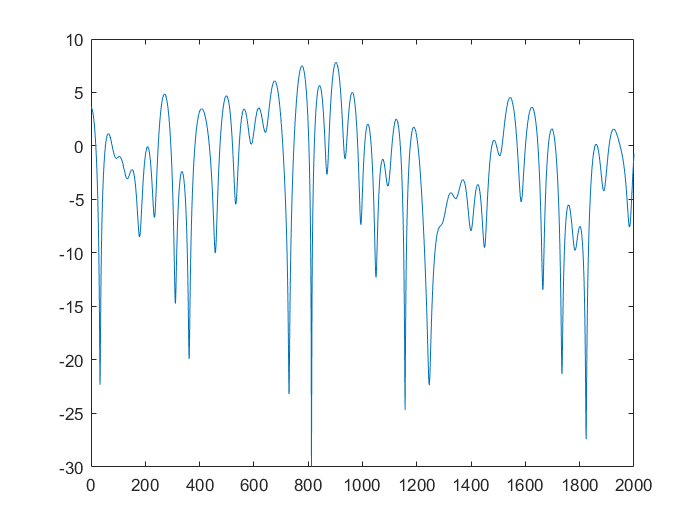

plot(20*log10(abs(out)))

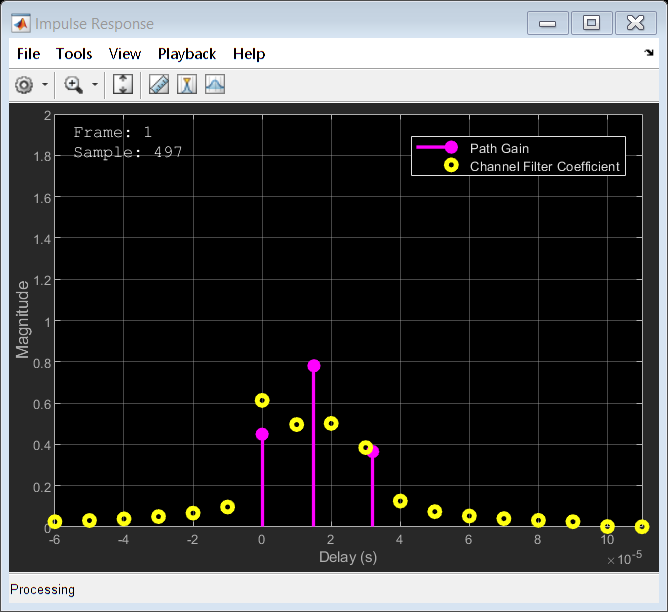

rayChan = comm.RayleighChannel('SampleRate',100000,'MaximumDopplerShift',130,...
    'PathDelays',[0 1.5e-5 3.2e-5],'AveragePathGains',[0, -3, -3],...
    'Visualization','Impulse response');
tx = randi([0 1],500,1);
dbspkMod = comm.DBPSKModulator;
dpskSig = dbspkMod(tx);
y = rayChan(dpskSig);